## This is an example for the use of SoptSC to scRNA-seq data (Joost et al. 2016)

- Inference of number of clusters in an unsupervised way

- Clustering cells

- Pseudotime and lineage inference

- Cell-cell communication network for a list of given ligand-recptor pairs and their targets

- Cluster-cluster signaling network derived from the cell-cell communication network

%   All details of the functions are given in the corresponding function
%   files. Plsease refer to each M file for the discriptions.
%
%   Results are save in the folder: Results
%
%   Contact: Shuxiong Wang (Email: shuxionw@uci.edu) 

## Add path

clear;
clc;
echo on;
addpath('Data');
addpath('NNDSVD');
addpath('symnmf2');
addpath('Signaling');
addpath('vinlinplot');
addpath('Results')

## Import data and normalization


Data_all = importdata('JoostData.txt');
data_matrix = Data_all.data;
allgenes = Data_all.textdata(2:end,1);

data = log10(data_matrix +1); % log normalization

## Run SoptSC to obtain clusters

resfolder = 'Results';
% NC is the number of clusters: can be specified by user, or
% if not given (NC = []), it will be inferred by SoptSC
NC = [];    
No_cells = size(data,2);
No_exc_cell = 0.03*No_cells;
No_features = 3000;

[W,No_cluster,cluster_label,H,eigenvalues] = SoptSC_cluster(data,...
    NC,No_exc_cell,No_features,resfolder);

Iter  Err
1, 19.587507
2, 18.565008
3, 17.576863
4, 16.649533
5, 15.784173
6, 14.977189
7, 14.224344
8, 13.521566
9, 0.611837
10, 0.337877
11, 0.310106
12, 0.297489
13, 0.286709
14, 0.276424
15, 0.266509
16, 0.256966
17, 0.247800
18, 0.233591
19, 0.212781
20, 0.185999
21, 0.153609
22, 0.115599
23, 0.072322
24, 0.043272
25, 0.106352
Number of cluster based on zero eigenvalues & Largest gap 
     4     7



## Plot eigen-spectrum for the inference of number of clusters

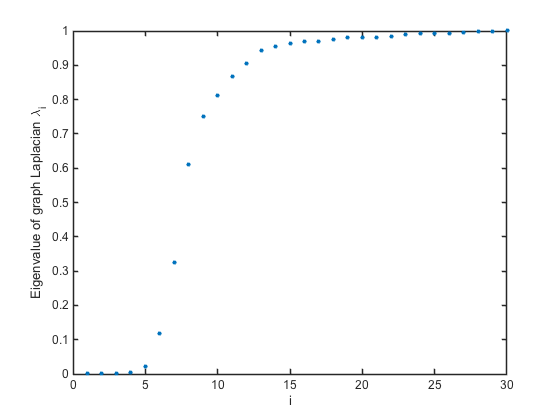

plot_eigengap(eigenvalues,resfolder);

## Visulization via dimension reduction (tSNE, PCA)

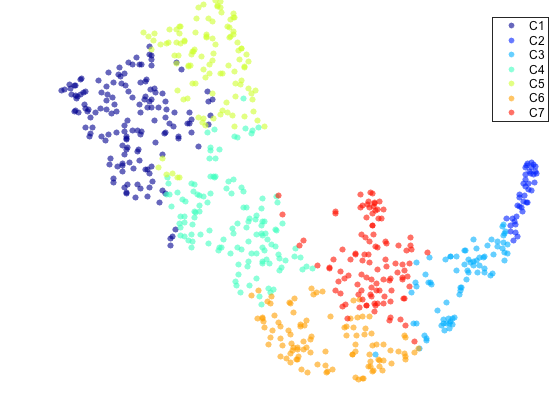

method = 'tsne';        % set method as 'pca' or 'tsne'
latent = plot_cluster(W,cluster_label,No_cluster,method,resfolder);

## Identification of marker genes and plots gene-cell heatmap of topn markers

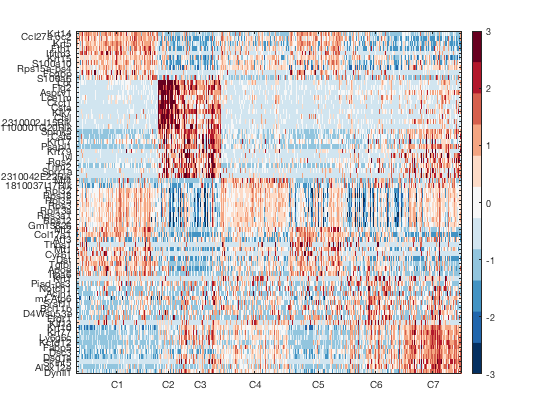

topn = 10;
Gene_idx = GC_htmp_DE(data,allgenes,cluster_label,topn,resfolder);

## Feature plots for selected markers

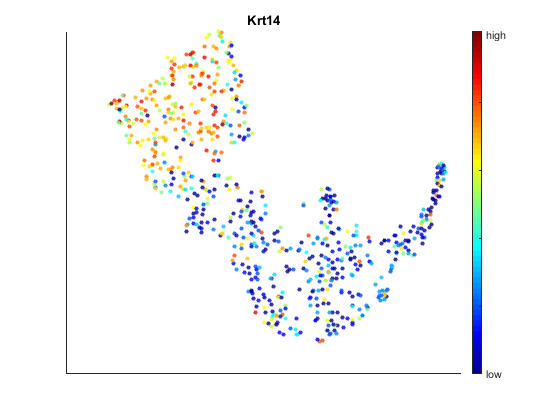

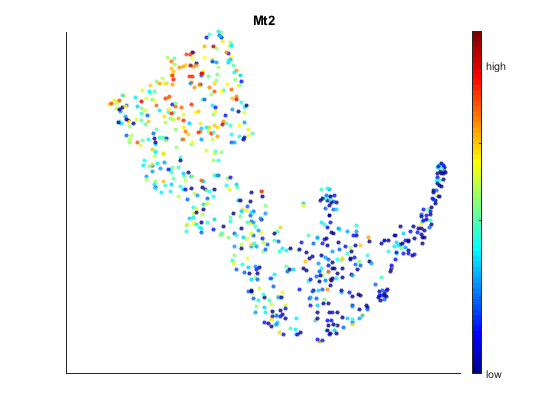

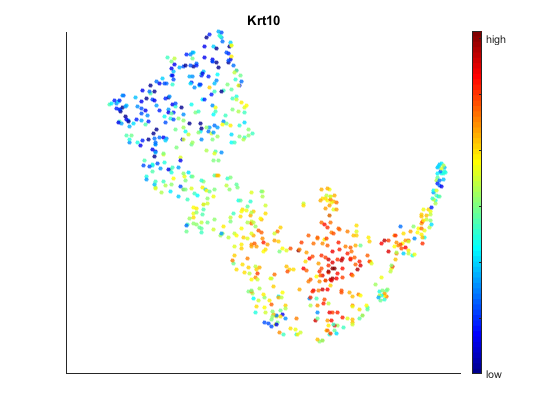

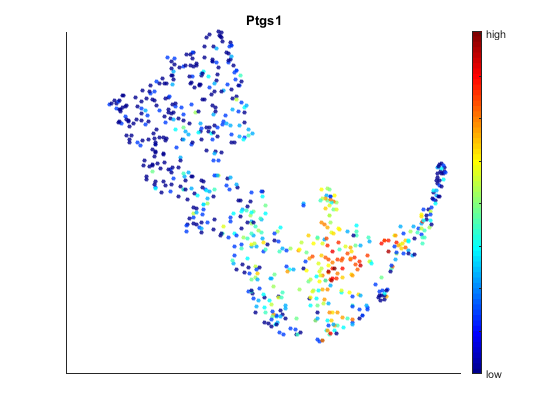

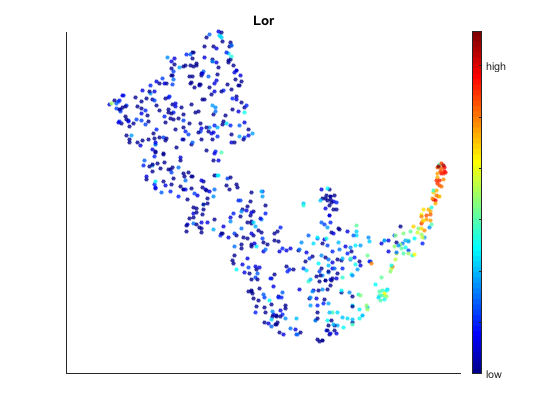

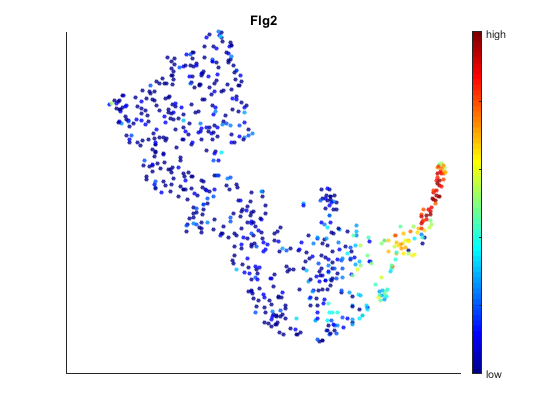

Marker = {'Krt14','Mt2','Krt10','Ptgs1','Lor','Flg2'};
plot_marker(data,Marker,allgenes,latent,resfolder) 

## Violin plot of the selected marker genes along clusters

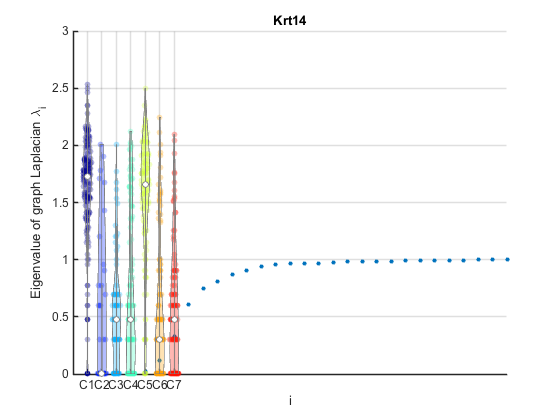

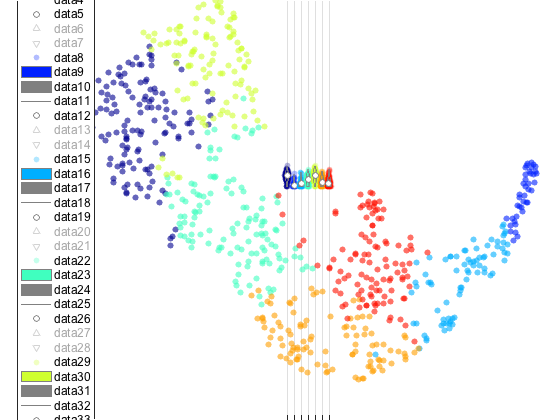

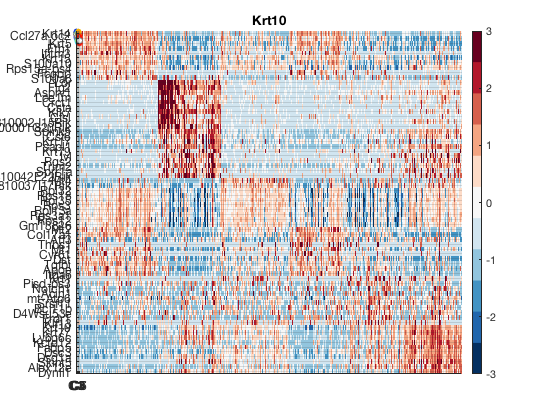

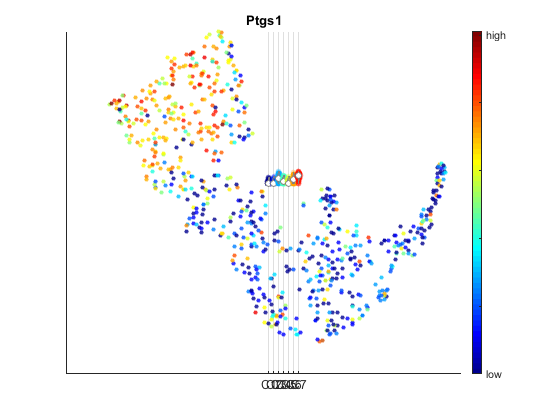

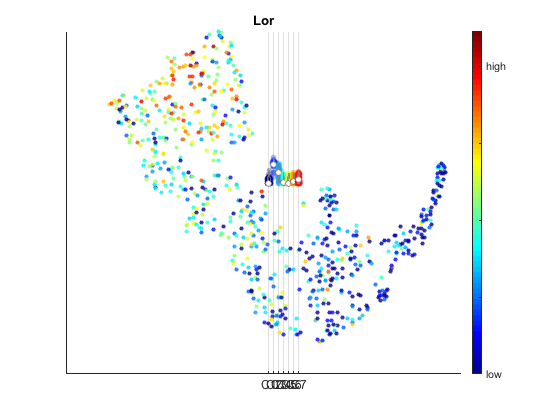

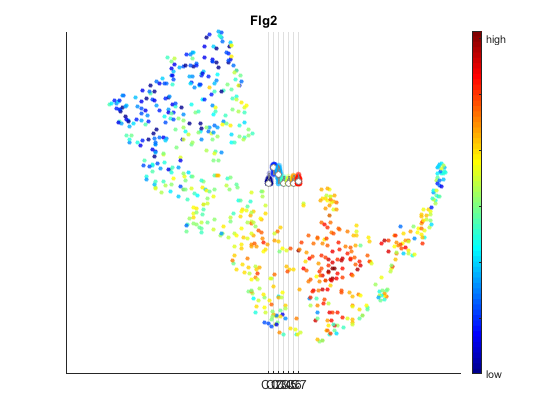

plot_marker_violin(data,allgenes,Marker,cluster_label,No_cluster,resfolder)

## Pseudotime and lineage inference

- root_cluster: root cluster (set as an integer). If root_cluster = 0, SoptSC infers the root cluster; otherwise, SoptSC uses the root cluster set by user.

- root_cell: root cell (set as an integer). If root_cell = 0, SoptSC infers the root cell; otherwise, SoptSC uses the root cell set by user.

- reverse: reverse the infer graph (0 or 1). If reverse = 0, SoptSC will not reverse the graph, otherwise SoptSC will reverse the graph 

Root cluster candidates:
     1     2

Inferred root cell is:


root_cell = 218

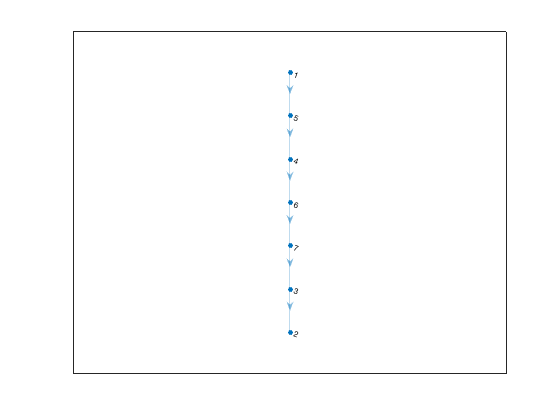

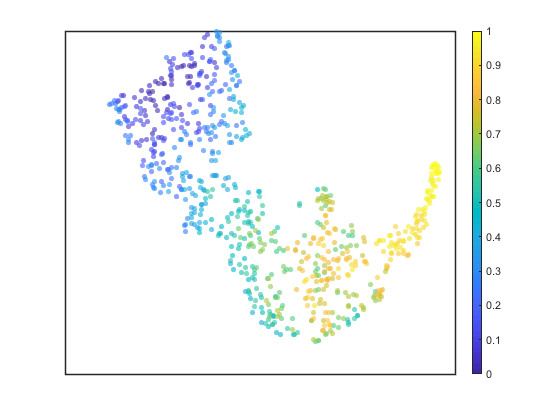

root_cluster = 0;
root_cell = 0;
reverse = 1;
[Lineage, Ptime,Cell_dist] = Lineage_Ptime(W,No_cluster,...
    cluster_label,root_cluster,root_cell,latent,reverse);

## Plot cluster color and pseudotime color on the lineage tree

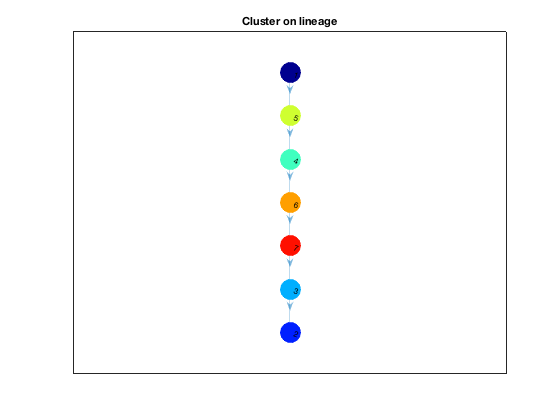

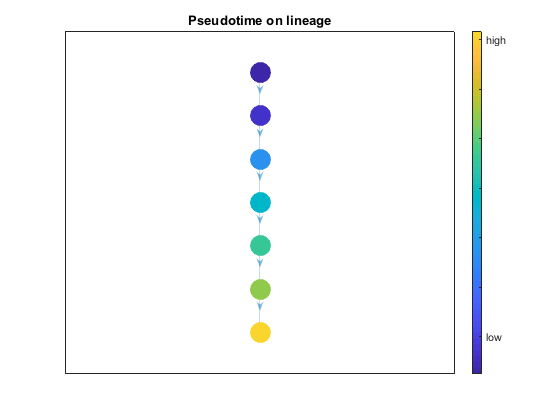

plot_lineage(Lineage,No_cluster,cluster_label,Cell_dist,resfolder);

## Plot pseudotime on latent space

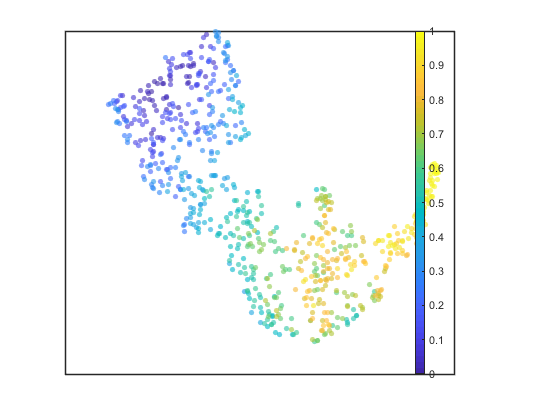

plot_pseudotime(latent,Ptime,resfolder);

## Plot marker gene on the lineage tree

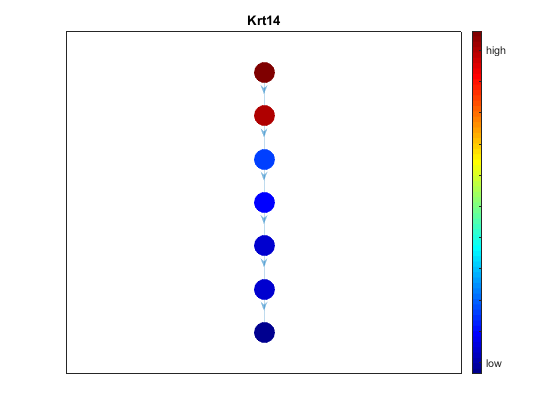

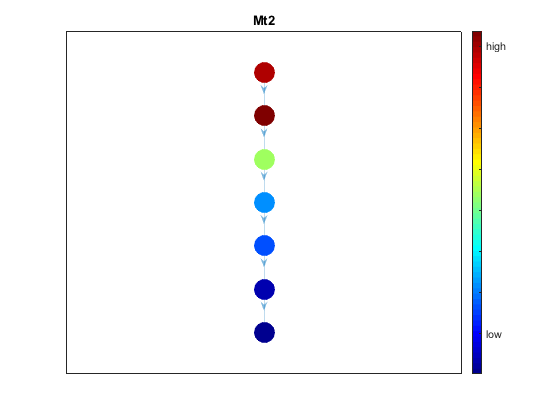

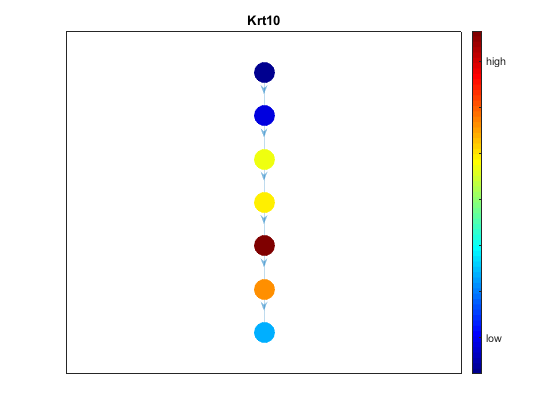

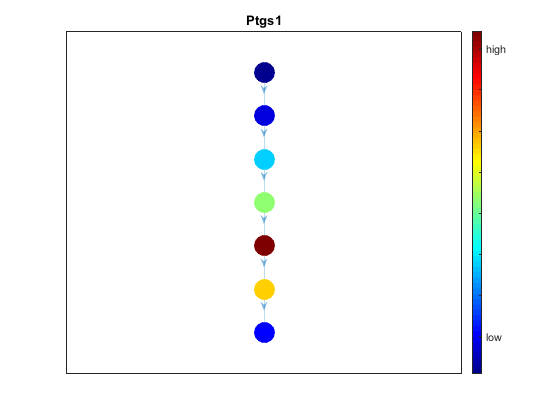

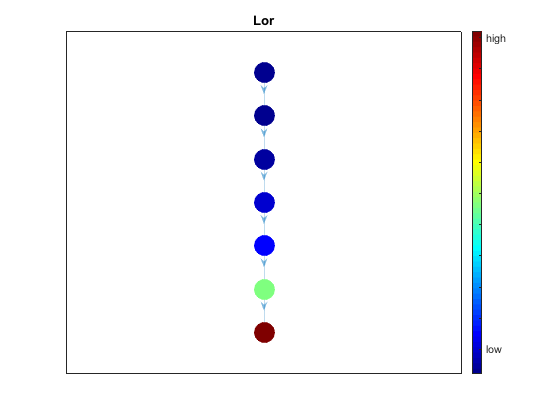

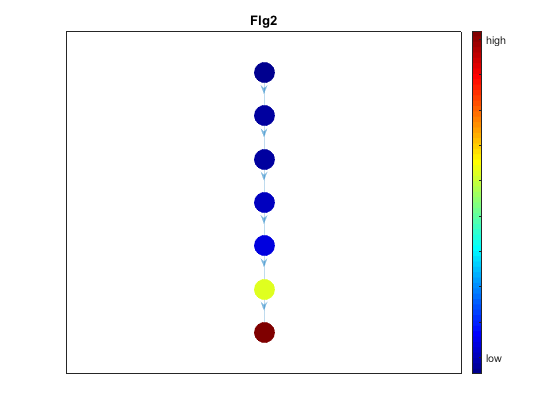

plot_lineage_marker(data,Lineage,allgenes,No_cluster,cluster_label,Marker,resfolder)